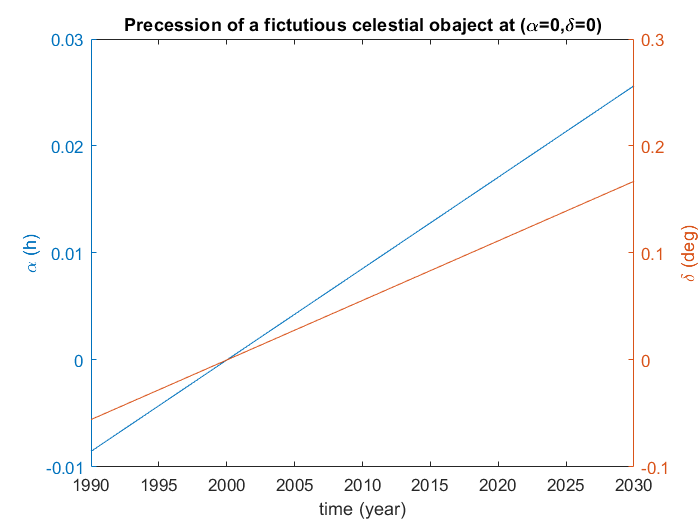

%--------------------------------------------------------------------------
%   
%          Introduction to Space Geodesy - Main
%   Assignment 4: Reference systems and transformations
% 
%   Author         : Group B
%   Version        : January 13, 2021
%
%--------------------------------------------------------------------------

clc;
clear all;
close all;
format longG

%% Task 1 - Precession

yyyy=1990:2030;
mm=1;
dd=1;
ut1=12;
minute=0;
second=0;

% coordinatesofa fictitious celestial object at the vernal equinox (0; 0) 
J2000_alpha = 0; 
J2000_delta = 0;

[x,y,z] = SphToCart(1,J2000_delta,J2000_alpha); 

counter = 0;

Calculated_delta = zeros(1,length(yyyy));
Calculated_alpha = zeros(1,length(yyyy));

%Loop for all Year
for i = yyyy

    counter = counter+1;

    [jd,~] = gre2jd(i,mm,dd,ut1,minute,second); %Running Julian Day

    P = precession(jd); %precession

    precCart = P * [x,y,z]';

    [r,alpha , delta] = CartToSphe(precCart(1),precCart(2),precCart(3));

    Calculated_delta(counter) = delta;
    Calculated_alpha(counter) = alpha;

end

alpha_ha = Calculated_alpha*12/pi; %To Hour angles
delta_deg = Calculated_delta/pi*180; %To degree

% Plot Task 1
figure % new figure
[hAx,~,~] = plotyy(yyyy,alpha_ha,yyyy,delta_deg);

title('Precession of a fictutious celestial obaject at (\alpha=0,\delta=0)')
xlabel('time (year)')

ylabel(hAx(1),'\alpha (h)') % left y-axis 
ylabel(hAx(2),'\delta (deg)') % right y-axis

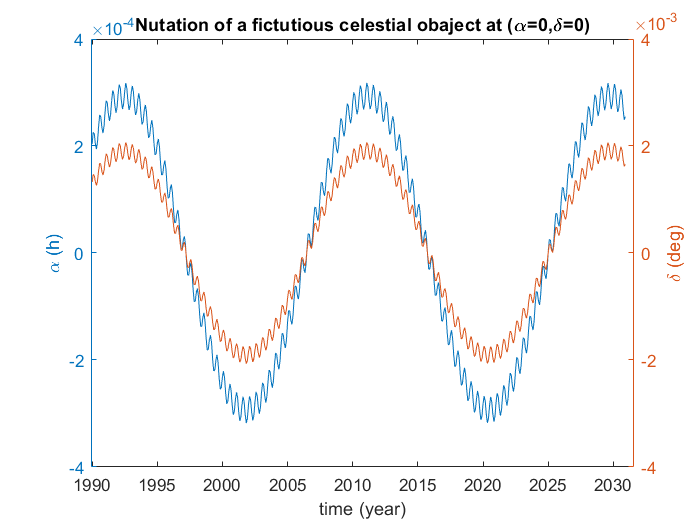

%% Task 2 - Nutation

yyyy=1990:2030;
mm=1:12;
dd=1;
ut1=12;
minute=0;
second=0;

% coordinatesofa fictitious celestial object at the vernal equinox (0; 0) 
J2000_alpha = 0; 
J2000_delta = 0;

[x,y,z] = SphToCart(1,J2000_delta,J2000_alpha); 

counter = 0;

Calculated_delta = zeros(1,length(yyyy)*length(mm));
Calculated_alpha = zeros(1,length(yyyy)*length(mm));

%Loop for all Year
for i = yyyy
    for k = mm

        counter = counter+1;

        [jd,~] = gre2jd(i,k,dd,ut1,minute,second); %Running Julian Day

        N = nutation(jd); %precession

        NutationCart = N * [x,y,z]';

        [r,alpha , delta] = CartToSphe(NutationCart(1),NutationCart(2),NutationCart(3));

        Calculated_delta(counter) = delta;
        Calculated_alpha(counter) = alpha;

    end
end

alpha_ha = Calculated_alpha*12/pi; %To Hour angles
delta_deg = Calculated_delta/pi*180; %To degree

% Plot Task 2
YYYYMM = 1:(length(yyyy)*length(mm));

figure % new figure
[hAx,hLine1,hLine2] = plotyy(YYYYMM,alpha_ha,YYYYMM,delta_deg);

set(gca, 'XTick', 1:60:(length(yyyy)*length(mm))); % Change x-axis ticks
set(gca, 'XTickLabel', yyyy(1:5:length(yyyy))); % Change x-axis ticks labels.

title('Nutation of a fictutious celestial obaject at (\alpha=0,\delta=0)')
xlabel('time (year)')

ylabel(hAx(1),'\alpha (h)') % left y-axis 
ylabel(hAx(2),'\delta (deg)') % right y-axis

%% Task 3 - Ploar Motion

[jd,~] = gre2jd(2021,6,11,0,0,0); %Running Julian Day

%test Values
yyyy=2021;
mm=3;
dd=6;
hour=2;
minute=13;
second=0; %17

polarMotion2021(yyyy,mm,dd,hour,minute,second)

ans =     1.0000    0.0000    0.0000
         0    1.0000   -0.0000
   -0.0000    0.0000    1.0000


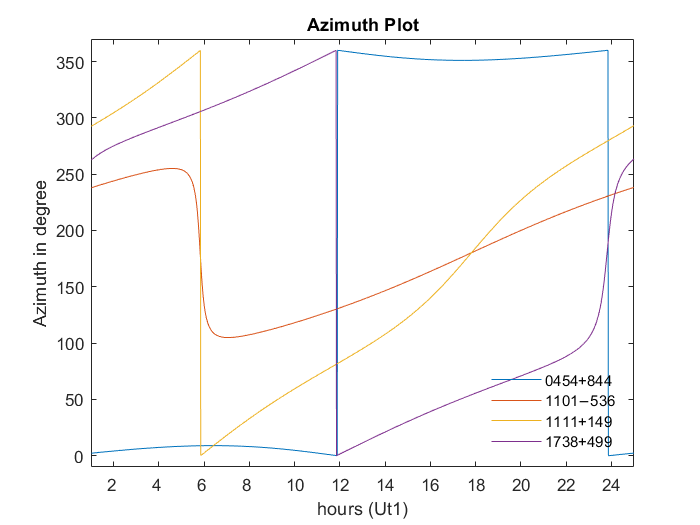

%% Task 4 Sykplot

ICRF3_Cordianes = struct;
ICRF3_Cordianes.sourceName = ["0454+844";"1101−536";"1111+149";"1738+499"];
ICRF3_Cordianes.alpha = [[05,08,42.36351222];...
    [11,03,52.22168463];...
    [11,13,58.69508613];...
    [17,39,27.39049431]];
ICRF3_Cordianes.delta = [[84,32,04.5441733];...
    [-53,57,00.6966389];...
    [14,42,26.9526507];...
    [49,55,03.3683385]];

%Fix values from Hour to degrees
ICRF3_Cordianes.alpha(:,1) = ICRF3_Cordianes.alpha(:,1) * 360/24;

%Convert values to decimaldegree
alpha_degrees = zeros(1,length(ICRF3_Cordianes.sourceName))';
delta_degrees = zeros(1,length(ICRF3_Cordianes.sourceName))';

for i = 1:length(ICRF3_Cordianes.sourceName)

alpha_degrees(i,1) = De_Mi_Se_To_DecDeg([ICRF3_Cordianes.alpha(i,:)]);
delta_degrees(i,1) = De_Mi_Se_To_DecDeg([ICRF3_Cordianes.delta(i,:)]);

end

ICRF3_Cordianes.alpha_rad = deg2rad(alpha_degrees);
ICRF3_Cordianes.delta_rad = deg2rad(delta_degrees);

%Get X,Y and Z for all objects

CartesianCoordinates  = zeros(length(ICRF3_Cordianes.sourceName),3);

for i = 1:length(ICRF3_Cordianes.sourceName)

 %delta = phi / alpha = lamda

    [x,y,z] = SphToCart(1, ICRF3_Cordianes.delta_rad(i,1),...
        ICRF3_Cordianes.alpha_rad(i,1)); 

    CartesianCoordinates(i,:) = [x,y,z];

end

ICRF3_Cordianes.CartesianCoordinates = CartesianCoordinates;

%calculate Azimuth and elevation

%observatory near Berlin
Lamda = De_Mi_Se_To_DecDeg([13,24,0]); %13°24′
Phi = De_Mi_Se_To_DecDeg([52,36,0]); %52°36′
M1 = ref3d(1);

%Left equation - time independent

LeEq = M1 * rot3d(((180/2)-Phi),2) * rot3d(Lamda,3);

%time
yyyy=2021;
mm=6;
dd=11;

%Loop

A = zeros(1,24*60);
E = zeros(1,24*60);

counter = 0;

ICRF3_Cordianes.HorizonCoordinates.Ob1 = zeros(24*60,2);
ICRF3_Cordianes.HorizonCoordinates.Ob2 = zeros(24*60,2);
ICRF3_Cordianes.HorizonCoordinates.Ob3 = zeros(24*60,2);
ICRF3_Cordianes.HorizonCoordinates.Ob4 = zeros(24*60,2);

fieldNames = fieldnames(ICRF3_Cordianes.HorizonCoordinates);

for ut1 = 0:23
    for minute = 0:59

        counter = counter+1;

        %Julain Date
        [jd,~] = gre2jd(yyyy,mm,dd,ut1,minute,0); 

        %JD2000 in centurys
        t = (jd - 2451545.0)/36525;

        %Greenwich Apparent Sidereal Time
        GMST = (F(jd)*86400 + 24110.54841 -86400/2 + ...
            8640184.812866 * t + 0.093104 * t * t -...
            6.2e-6 * t * t * t)/3600; % hour

        %Get Hours of a Day
        GMST = Get_Hours_From_HourCycles(GMST);

        %GMST to rad
        GMST = GMST*15;

        %Ploar Motion
        W = polarMotion2021(yyyy,mm,dd,ut1,minute,0);

        %Precession
        P = precession(jd);

        %Nutation
        N = nutation(jd);

        %Objects

        for k = 1:length(ICRF3_Cordianes.sourceName)

            Xg = LeEq * W * rot3d(GMST,3) * N * P *...
            ICRF3_Cordianes.CartesianCoordinates(k,:)';
            A = atan2d(Xg(2),Xg(1));
            E = atand(Xg(3)/sqrt(Xg(1)^2 + Xg(2)^2));

            %Shift Azimuth definition interval

            if(A<0)
                A = A + 360;
            end

            ICRF3_Cordianes.HorizonCoordinates.(fieldNames{k})(counter,:) = [A,E];
        end
    end
end

%% Plot times series

%Azmiut Plotting

Xaxis = 1:(24*60);

figure;
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob1(:,1))
axis([0,24*60,0-10,370])
hold on;
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob2(:,1))
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob3(:,1))
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob4(:,1))
hold off
set(gca, 'XTick', 60:(60*2):(24*60)); % Change x-axis ticks
set(gca, 'XTickLabel', 2:2:24); % Change x-axis ticks labels.
title('Azimuth Plot');
ylabel('Azimuth in degree');
xlabel('hours (Ut1)');
legend(ICRF3_Cordianes.sourceName(1),ICRF3_Cordianes.sourceName(2),...
    ICRF3_Cordianes.sourceName(3),ICRF3_Cordianes.sourceName(4),'Location','southeast')
legend('boxoff')

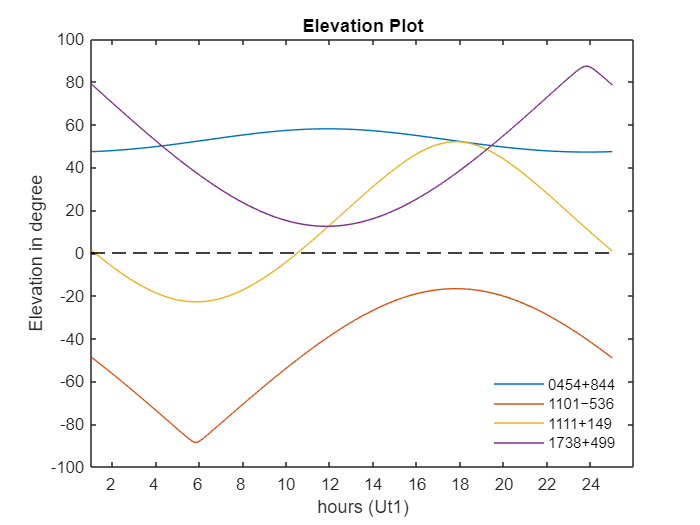

%Elevation Plotting

Xaxis = 1:(24*60);

figure;
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob1(:,2))
hold on;
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob2(:,2))
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob3(:,2))
plot(Xaxis,ICRF3_Cordianes.HorizonCoordinates.Ob4(:,2))
hold off
set(gca, 'XTick', 60:(60*2):(24*60)); % Change x-axis ticks
set(gca, 'XTickLabel', 2:2:24); % Change x-axis ticks labels.
title('Elevation Plot');
ylabel('Elevation in degree');
xlabel('hours (Ut1)');
x = [0 (24*60)];
y = [0 0];
line(x,y,'Color','black','LineStyle','--')
legend(ICRF3_Cordianes.sourceName(1),ICRF3_Cordianes.sourceName(2),...
    ICRF3_Cordianes.sourceName(3),ICRF3_Cordianes.sourceName(4),'Location','southeast')
legend('boxoff')

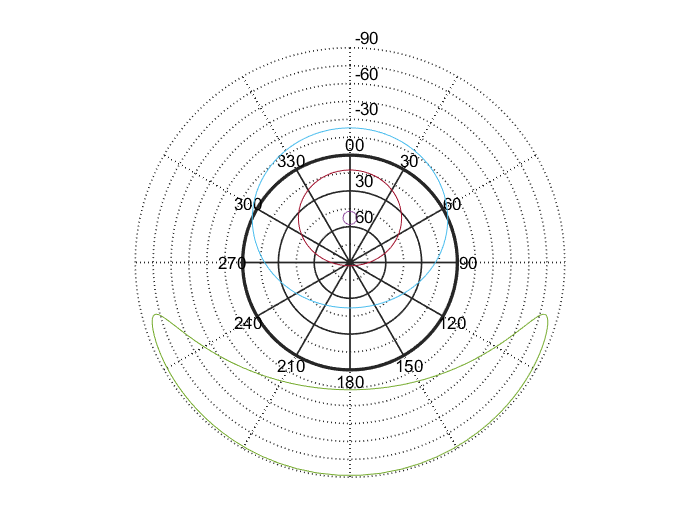

%% skyplot


azmiut = [ICRF3_Cordianes.HorizonCoordinates.Ob1(:,1),...
    ICRF3_Cordianes.HorizonCoordinates.Ob2(:,1),...
    ICRF3_Cordianes.HorizonCoordinates.Ob3(:,1),...
    ICRF3_Cordianes.HorizonCoordinates.Ob4(:,1)];

elevation = [ICRF3_Cordianes.HorizonCoordinates.Ob1(:,2),...
    ICRF3_Cordianes.HorizonCoordinates.Ob2(:,2),...
    ICRF3_Cordianes.HorizonCoordinates.Ob3(:,2),...
    ICRF3_Cordianes.HorizonCoordinates.Ob4(:,2)];

skyplot(azmiut,elevation,'-');
ylabel('Elevation in degree');